#  ** Note: this is a work in Progress - not for public release

JHynes: 03/12/2019

#  1. cSIMNETS or lfpNETS Live Matlab Tutorial Overview (work in progress)

                                                                  --------------------------------------------------------------------------------------------------

What is the SIMNETS algorithm? The SIMNETS algorithm is designed to compute a  Functional Similarity Map for a population of simultaneously recorded neurons or LFP signals, jointly referred to here as 'nodes', calculate the optimal number of sub-nets (i.e., node clusters) in the map, and then graphically display a 3D visualization of the Node Similarity Map containing the sub-nets. Note: this algorithm does not require knowledge of the node tuning functions (or even that they have any defined tuning functions) or knowledge of the information encoded in on individual trials, i.e., the specific internal or external covariate(s) that the nodes  are responding to.

**INPUTS**: Although there are several input paramters that can be changes in the SIMNETS algorithm, 5 are required: 

- LFP signals: extracted LFP signals ( time x trials x neurons)

- LFP sample rate: in hz. 

- lfp type ids: electrodes labeled, or computational-node type labels.

                                                             --------------------------------------------------------------------------------------------------

Cite: please cite the DOI for the SIMNETS paper and the DOI for the Software Repository (doi: xxxx) when using this software and/or this analysis framework for analyzing your own data. 

 [1] SSIMS and SIMNETS toolbox: DOI: https://doi.org/  

[2] Jacqueline Hynes, David Brandman,  Jonas Zimmerman, John Donoghue, Carlos Vargas-Irwin (2018). "SIMNETS: a computationally efficient and            scalable framework for identifying networks of functionally similar neurons" . DOI: https://doi.org/10.1101/463364)       

[3] Vargas-Irwin, C. E., Brandman, D. M., Zimmermann, J. B., Donoghue, J. P., & Black, M. J. (2015).  "Spike Train SIMilarity Space (SSIMS): A Framework for Single Neuron and Ensemble Data Analysis (2014)."

[4 ] Victor, Jonathan D. “Spike train metrics” Current opinion in neurobiology vol. 15,5 (2005): 585-92.

[5] .J.P. van der Maaten and G.E. Hinton. Visualizing High-Dimensional Data Using t-SNE. Journal of Machine Learning Research 9(Nov):2579-2605, 2008.

@author Jacqueline Hynes. Copyright (c) Jacqueline Hynes, Brown University. All rights reserved.

Questions? Contact  <Jacqueline Hynes@Brown.edu> or <Carlos Vargas_irwin@brown.edu>  

# I - Load Data;

Load LFP signal matrix. Signals should be stored in a double array as (time x trials x electrodes). Sample rate should be stored with the LFP signals or added as a variable. 

The Demo Data consist of simulated LFP signals (i.e., sinewaves) for 25 electrode and 20 trials. The hz of the LFP signals changes on certain subsets of trials. The Pattern of change differs  across electrodes to result in 3 ground-truth sub-nets. 

load('LFP_SimulatedSignals_DemoData.mat')
 
%lfpSignals = lfpSignals(time, trials, neurons);
 nT = size(lfpSignals,1);
 nS = size(lfpSignals,2);
 nN = size(lfpSignals,3);
 

  **Plotting:** 

**        a) LFP Signals For Each Electrode (time x trials)**

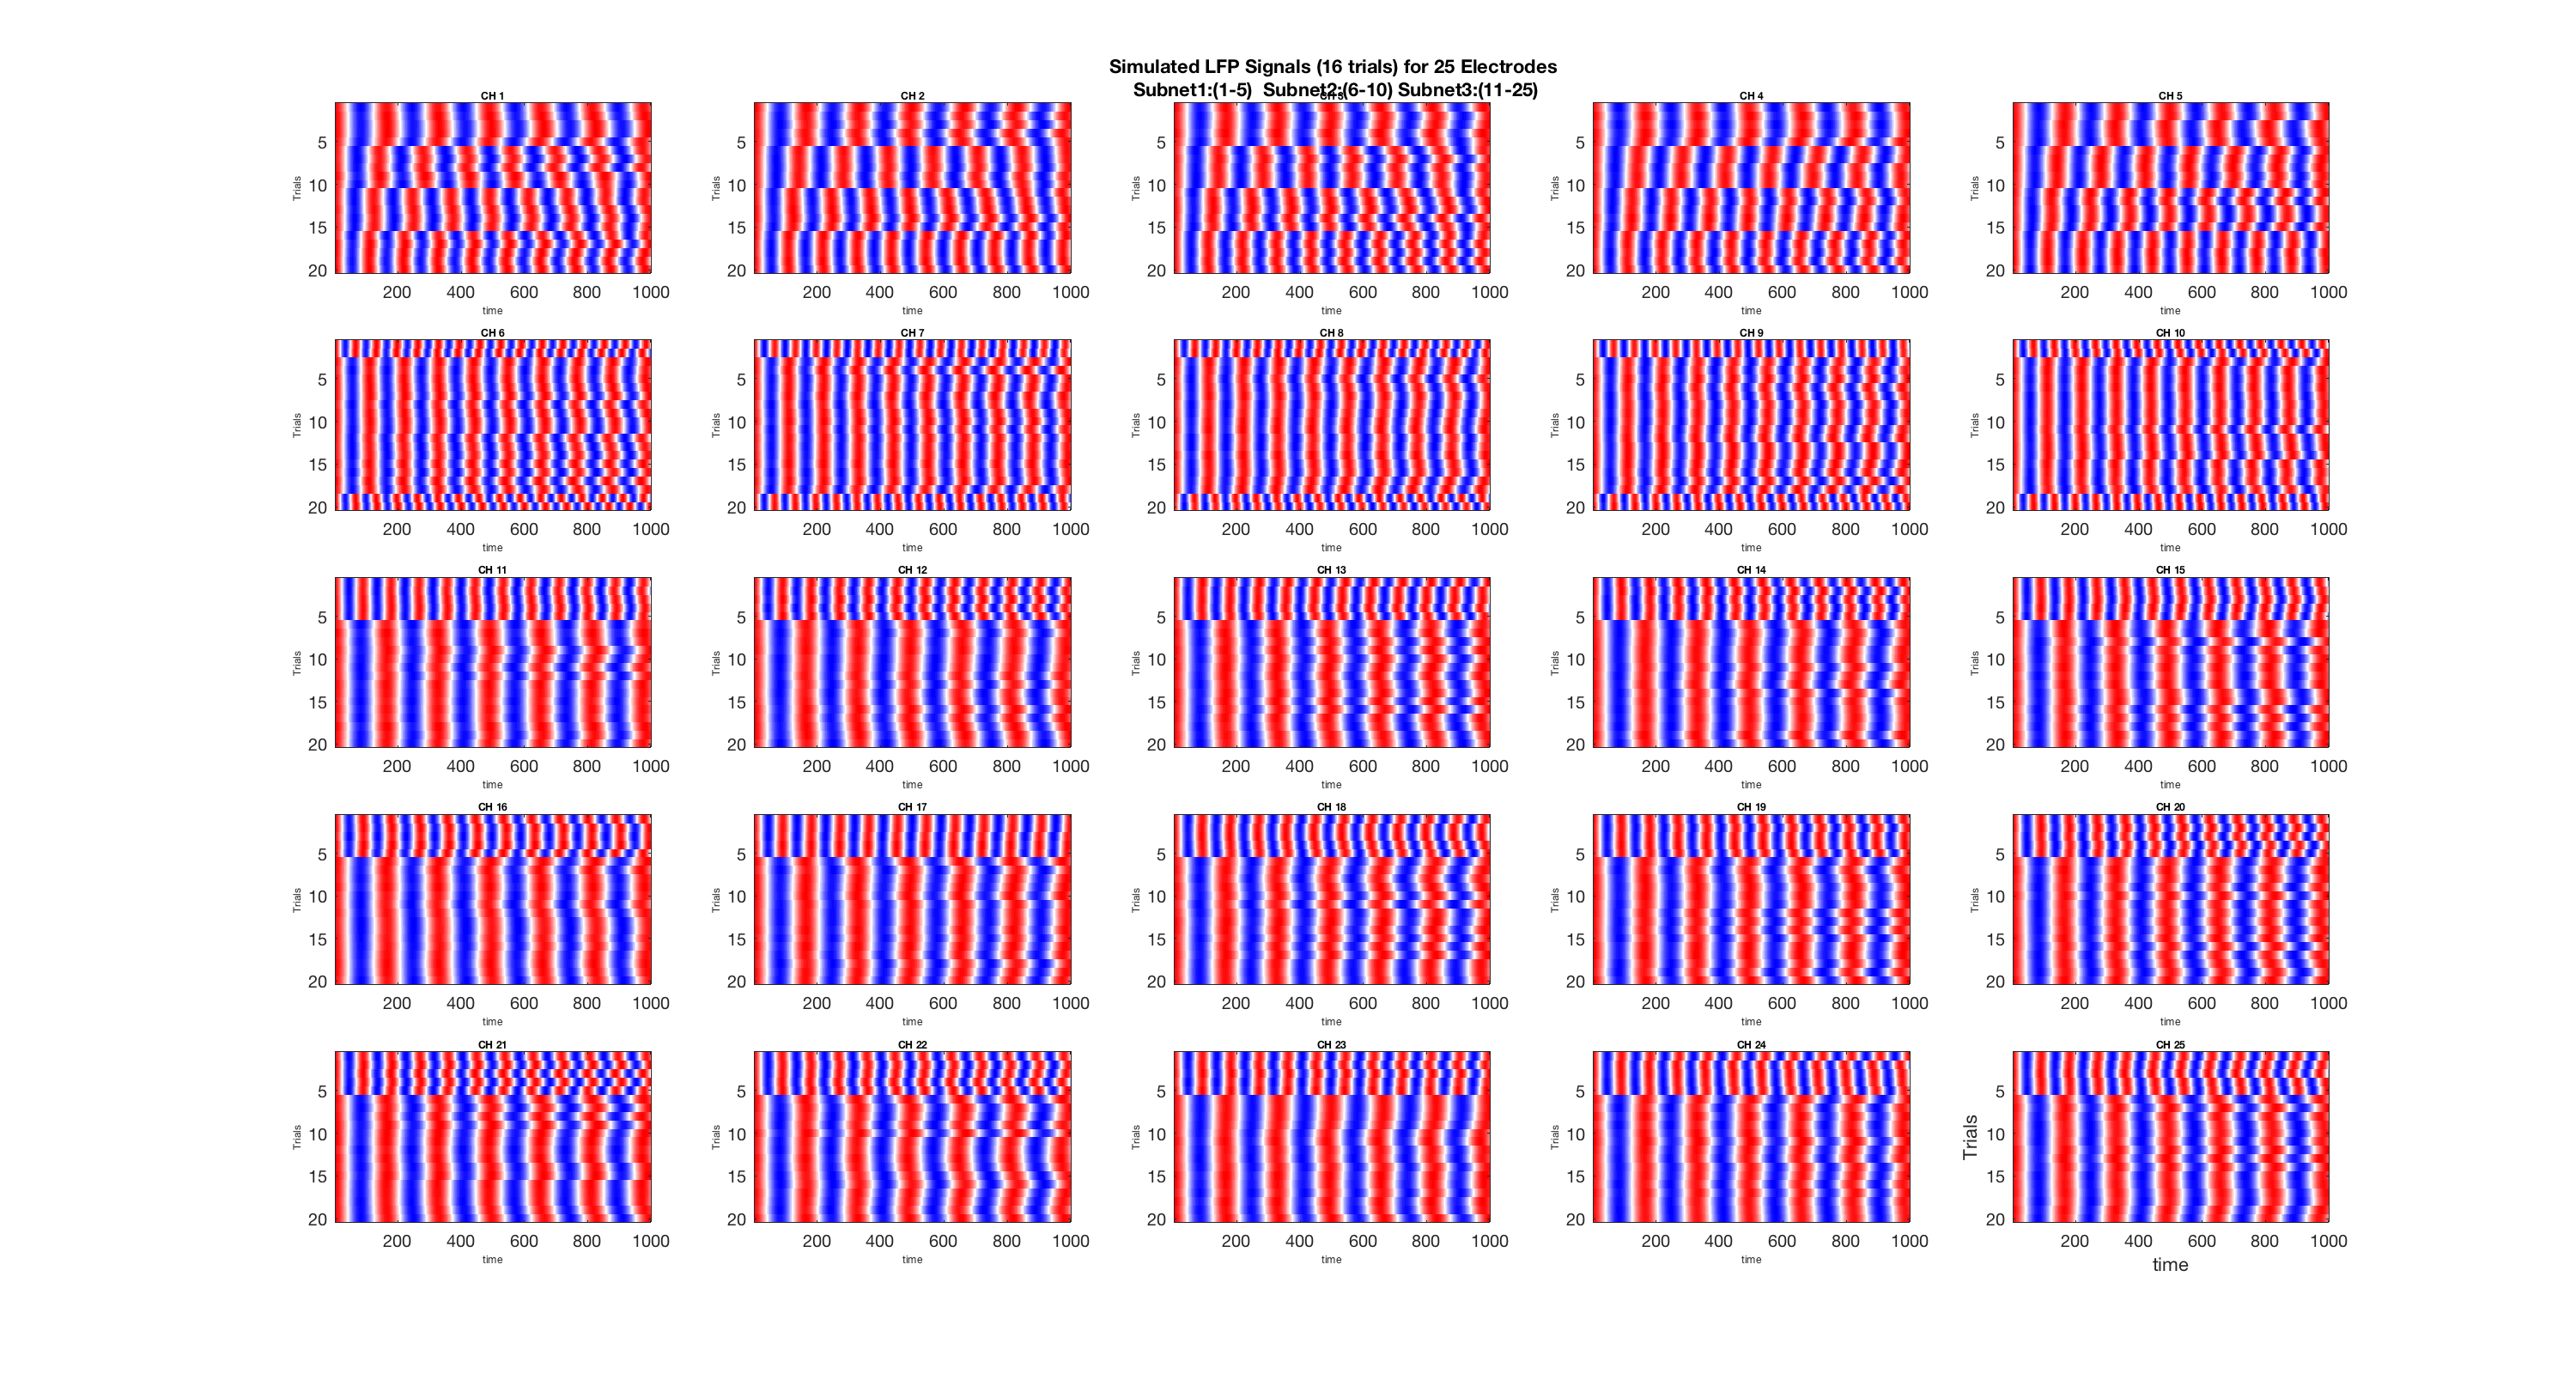

    for x = 1:nN
        
      subplot(ceil(nN/5),5,x); 
      imagesc(lfpSignals(:,:,x)'); 
      colormap redblue
      title( ['CH ' num2str(x) ], 'fontsize', 6);
       xlabel('time','fontsize', 6); 
       ylabel('Trials','fontsize', 6)
      
    end
   xlabel('time'); 
   ylabel('Trials')
   supertitle ({'Simulated LFP Signals (16 trials) for 25 Electrodes'; ' Subnet1:(1-5)  Subnet2:(6-10) Subnet3:(11-25)'})
   set(gcf, 'position',[  100  400   1500     800]) 

# II - Set-up Parameters:

% Parameters: c-SIMNETS
  
  sampleRate =1000; 
  
  win_len = nT/sampleRate;
  
  perplexity = 20;
  
  clusterdim = 20; 
  displaydim = 3;    
  crange =10;
  
  iterations = 0; 
  
% Parameters LFP analysis 
  params.fpass = [1 20];  % Selection of frequency band

   params.tapers =[15 19];
   params.pad = 0; 
   params.Fs = sampleRate;
 
   params.trialave = 1; 
   p = 0.05;
   params.err = [0 p];
   timestep =win_len;
   movingwin = [ win_len timestep];

# III - Run lfp-NETS

## 1) Calculate Intrinsic LFP similarities

 xcorrh_SSIM = cell(nN,1);
 matSim = zeros(nS,nS); 


 nn = 1;
 
 for x = 1:size(lfpSignals,3)
      
     CH =  lfpSignals(:,:,x);
 
      for sigx = 1:size(lfpSignals,2)
          
          for sigy = 1:sigx
              
              [ C ,phase, S12, S1, S2, time, fq] = cohgramc(CH(:,sigx) , CH(:,sigy)  , movingwin, params);

                matSim(sigx, sigy) = mean(C); 
         
                % Calculate correlation between Neuron A and Neuron B's intrinsic spike train distances 
                % NSmat(n1,n2) = corr(C,B(:) , 'type', 'pearson');    
         
          end

      end
      
    matSym = tril(matSim)+tril(matSim,-1)'; 
    
    xcorrh_SSIM{nn} = 1-matSym; 
     
    nn = nn+1; 
    
 end

**Plotting:**

**Example SSIM matrices for four neurons  **

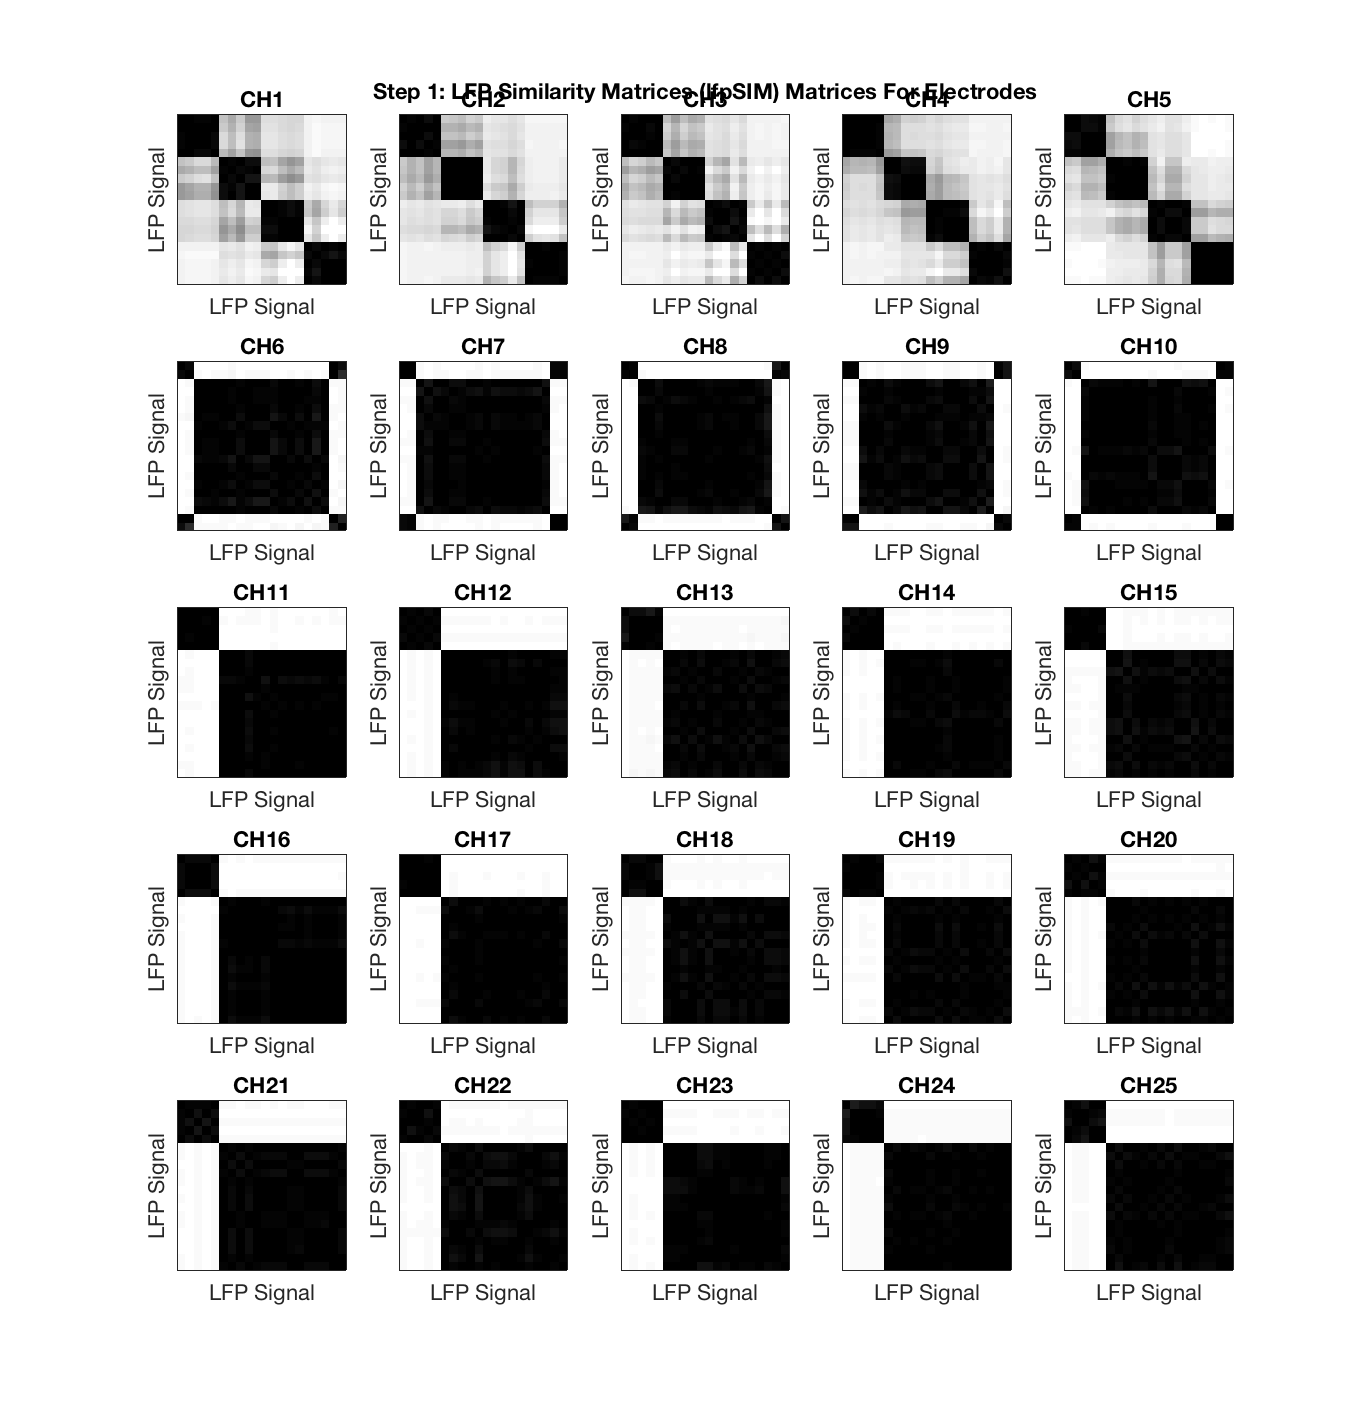

figure
    for nn = 1:nN
             
      subplot(ceil(nN/5),5,nn); 
      
      h=imagesc(xcorrh_SSIM{nn});
      
      title(['CH' num2str(nn)]); 
      set(gca,'XTick',[], 'YTick', []); 
      xlabel('LFP Signal'); 
      ylabel('LFP Signal')  
       colormap gray 
    end       
    supertitle(['Step 1: LFP Similarity Matrices (lfpSIM) Matrices For Electrodes']);
    set(gcf, 'position',[680   270   681  714]); 

##  2) Calculate NxN LFP Similarity Matrix

     lfpSMat  =  zeros(nN, nN); 

 for x = [ 1:nN ]
     
     for y = [1:x]
         
         lfpSMat(x,y) = corr( xcorrh_SSIM{x}(:), xcorrh_SSIM{y}(:) , 'type' , 'pearson');   
   
     end 
     
 end
 
 lfpSMat = tril(lfpSMat)+tril(lfpSMat,-1)'; 

    
 

## ) Perform Dimensionality Reduction on NxN Neuron Similarity Matrix

Use a dimensionality reduction algorithm, such as tSNE, to reduce the N LFP similarity correlation vectors to a lower dimensional space for the clustering step (e.g., 5-10 dimensions). The 'tsne_PCA' function performs PCA before tSNE to ensure a stable output. The top three dimensions are selected using PCA for the visualization step (step 4).   

- **Inputs:** LFP Similarity Map;  number of dimensions for the clustering step; perplexity value 

- **Outputs:** low-dimensional represenation of the NxN LFP Similarity Map (See Fig. 3) 

    LFPmapHD = runtSNE( lfpSMat,clusterdim,perplexity); 

Invalid MEX-file '/Users/jhynes/Documents/GitHub/PrivateRepository/BETA_SSIMS-and-SIMNETS-Toolbox/for_MATLAB/runtSNE.mexmaci64': dlopen(/Users/jhynes/Documents/GitHub/PrivateRepository/BETA_SSIMS-and-SIMNETS-Toolbox/for_MATLAB/runtSNE.mexmaci64, 6): Library not loaded: /usr/local/opt/armadillo/lib/libarmadillo.7.dylib
  Referenced from: /Users/jhynes/Documents/GitHub/PrivateRepository/BETA_SSIMS-and-SIMNETS-Toolbox/for_MATLAB/runtSNE.mexmaci64
  Reason: image not found

    
    FS_PC  = pca(LFPmapHD);                     % Perform PCA on the lower-dimensional t-SNE output structure
    
    LFPmap = LFPmapHD * FS_PC(:,1:displaydim);     % Select top 2/3 dimensions for plotting. 
     

 **P****lotting 3:**** t-SNE reduced Neuron Similarity matrix  **

     figure
     imagesc(LFPmapHD)
     colormap gray 
     set(gcf, 'position',[680   468  426  346]);
     h = colorbar;
     colormap gray
     ylabel(h, 'tsne co-ordinates');
     ylabel('Neurons')
     xlabel('Dim')
     title(['Step 3: tSNE Field Similarity Structure']);

## 4a)  Cluster Detection: silhouette analysis,  k-means clustering, significance testing

Use k-means clustering tool to cluster neurons in to 'k' cluster, where an optimal k value is calculated using a silhouette analysis. The larger the avg. silhouette value for a given value of k, the better the cluster solution.    

**Silhouette test: **

    [ silhouette clusterindex nclus  ] = autokmeanscluster( crange  , LFPmapHD );
   
    [sMax kIndex] =    max(silhouette);
    

**Silhouette value significance test: **

 This step is skipped is  `iterations = 0. `

   
   %[ ncmatShift, shufMU, shufCI] = SSIMSNeuronRelCorr_shuffleTest( SSIMmats, iterations, perp );  


**Pl****otting 4: Silhouette Plot**

 
    figure
    
    plot(2:max(crange), silhouette(2:max(crange)),'ko-', 'linewidth',1.5);hold on; 
    plot(kIndex, sMax,'ro', 'markersize',5);
    box off
    hold on; 
    xlabel('cluster Number')
    ylabel('mean sil. values')   
    xlim([ 2 max(crange)])
    set(gcf, 'position',[ 680   855   426   243]);
    set(gca,'linewidth',2)
    title([ 'Step 4a: Silhouette Plot - showing optimal cluster number = ' num2str(kIndex) ])
 

# Final Plotting: 

**Plotting:** 

**a) Field Similarity Map (with computational-node type labels)**  

subplot(1, 2, 1); 
plotNT(LFPmap,1:nN,'color', hsv(nN+2), 'msize', 10); 

title('Field Potential Similarity Map (with node type labels)', 'fontsize' , 12); 

    

**b) Field Similarity Map (with sub-net assignment labels)  **

subplot(1, 2, 2); 
plotNT(LFPmap,clusterindex,'msize',  10); 

set(gcf, 'position',[  184  410   1117     460]) 
title('Field Potential Similarity Map (with k-means cluster labels)' , 'fontsize' , 12); 
 
supertitle(['Step 4b: Neuron Similarity Map']);
        